noise floor estimation 

generating a signal

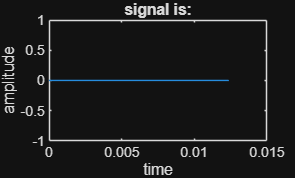

fs=8000; %sampling frequency 8000 samples taken in every second
T=5; %duration
t=0:1/fs:T-1/fs;% making a time axis
% signal
%burst in signal
signal = zeros(size(t)); signal(10000:15000)=sin(2*pi*1000*t(10000:15000)); 
signal(25000:30000)=2*sin(2*pi*2500*t(25000:30000));
%x1=sin(2*pi*1000*t);%1000hz signal fs>=2fm 
%x2=2*sin(2*pi*2500*t);%2500 hz signal
% plot(t(1:100),x1(1:100));
% plot(t(1:100),x2(1:100)); 
%signal=x1+x2;
plot(t(1:100),signal(1:100));
xlabel("time");
ylabel("amplitude");
title("signal is:");

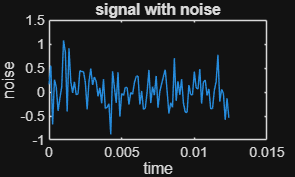

%add noise
noise=0.3*randn(size(signal));
%recieved signal
x=signal+noise;
plot(t(1:100),x(1:100));
xlabel("time");
ylabel("noise");
title("signal with noise");

% adding the frame length
frameLength = 1024;
hopSize = 512;
numFrames = floor((length(x)-frameLength)/hopSize)+1;
% adding a window
window=hann(frameLength);% returns a column vector 
NFFT = frameLength;

Power = zeros((NFFT/2)+1,numFrames);


for k = 1:numFrames

    index = (k-1)*hopSize + (1:frameLength);

    frame = x(index);

    frame = frame .* window';% transposing turns it into row vector

    X = fft(frame,NFFT);

    X = X(1:NFFT/2+1);
Power(:,k)=abs(X).^2;

end
% alpha=0.8
% smoothpower=zeros(size(Power));
% smoothpower(:,1)=Power(:,1);
% for k=2:numFrames
%     smoothpower(:,k)=alpha*smoothpower(:,k-1)...
%        + (1-alpha)*Power(:,k);
% end
%     L=20;
%     NoiseEstimate=zeros(size(smoothpower));
% for k = L:numFrames
% 
%     NoiseEstimate(:,k) = min(smoothpower(:,k-L+1:k),[],2);
% 
% end
% NoiseFloor = NoiseEstimate(:,end);

 NoiseFloor = median(Power,2);% median will give background noise as it do not include few signal spikes
NoiseFloor_dB = 10*log10(NoiseFloor + eps);

AveragePSD = mean(Power,2);% this will give signal spikes + background noise
% 
 AveragePSD_dB = 10*log10(AveragePSD + eps);

% creating the frequency axis
f = (0:NFFT/2)*fs/NFFT;
[maxVal, maxIdx] = max(AveragePSD_dB);% gives the maximum value (peak) and (peak)index value of spectrum
fprintf('Peak at %.1f Hz, %.2f dB above noise floor\n', ...
    f(maxIdx), maxVal - NoiseFloor_dB(maxIdx));

Peak at 2500.0 Hz, 30.99 dB above noise floor


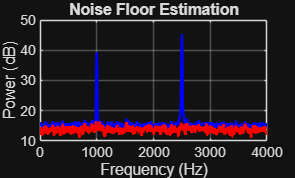


figure

 plot(f,AveragePSD_dB,'b','LineWidth',1.5)
 
 hold on

plot(f,NoiseFloor_dB,'r','LineWidth',2)

grid on

xlabel('Frequency (Hz)')
ylabel('Power (dB)')


title('Noise Floor Estimation') 

% as signal is present in every frame therefore median method made average
% spectrum equal to noise floor median method is not desirable for
% continuous signals